mat_dir_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Mat_files";
picture_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Slike_CV";

load (mat_dir_path + "/Samsung_30Q_18650_pack.mat");
load (mat_dir_path + "/VoltaicSystems_P110.mat");
load (mat_dir_path + "/Realisticno_ozracenje.mat");
load (mat_dir_path + "/MPP_param.mat");
load (mat_dir_path + "/CV_param.mat");

addpath(genpath("/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Functions/"));
addpath("/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Simulink/");

## Boost param:

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Granicni uvjet filter:
boost.Tgf = 1/(pi*1000);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 100 * 10^-3;
boost.Ru = 1;
boost.L = 40 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = (Bat.Qbat_tot)/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV setup:

% CCM:
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv = calc_pv_res("Solar_v2", pv_in);

## Operating point:

sim_op.Upv0 = pv.Umpp;
sim_op.Ipv0 = pv.Impp;
sim_op.Uoc = 12.10001;
sim_op.Ubat0 = sim_op.Uoc;
sim_op.E0 = Bat.Ebat_min + (sim_op.Uoc - Bat.Ubat_cut_off)*1/Bat.nagib;

sim_op.CV_limit = 12.1;
sim_op.Ubat_ref = 12.2;

% sim_op.m0 = 3.0002e+04;
% sim_op.m0 = 2.0825e+04

## Step setup:

stepp.sim_time = 0.3;
stepp.step_time = 0.1;

## Irradiance signal

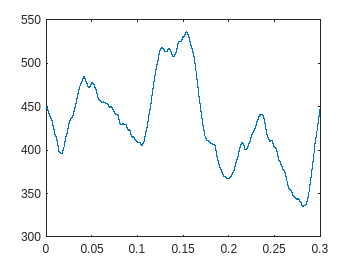

sim_time = stepp.sim_time;
Tstep = sim_time/20000;

GI = irradiance_signal_real(sim_time, Tstep, 200, 700);

figure;
plot(GI.Time, GI.Data);

## Simulacija:

% MPP_response = sim("Full_model.slx");
MPP_response = out;
save(mat_dir_path + "/Full_sim2.mat", "MPP_response")

## Simuliranja

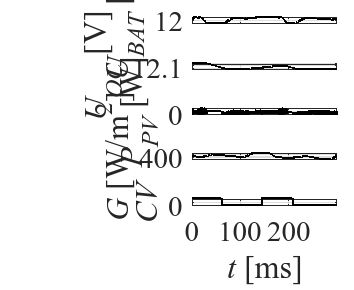

t = MPP_response.get("Ubat").Time * 1000;
Ubat = MPP_response.get("Ubat").Data;
IL = MPP_response.get("IL").Data;
Gir = MPP_response.get("Gir").Data;
Uoc = MPP_response.get("Uoc").Data;
CV = MPP_response.get("CV").Data;

% % --- Cut first 10 ms ---
% t_start = 5;          % [ms]
% idx = t >= t_start;
% 
% t    = t(idx) - t_start;   % reset time to 0 if desired
% Ubat = Ubat(idx);
% IL   = IL(idx);
% Gir  = Gir(idx);
% Uoc  = Uoc(idx);
% CV   = CV(idx);

% --- Reduce sample density ---
step = 10;             % plot every 10th sample
t    = t(1:step:end);
Ubat = Ubat(1:step:end);
IL   = IL(1:step:end);
Gir  = Gir(1:step:end);
Uoc  = Uoc(1:step:end);
CV   = CV(1:step:end);


% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 4 x 1 array of graphs:
layout = tiledlayout(5,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

nexttile;
plot(t, Ubat, '-k', 'LineWidth', 1.8);
hold on;
grid on;
ylabel("\it{U_{BAT}}\rm [V]");
axis tight;
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
plot(t, Uoc, '-k', 'LineWidth', 1.8);
hold on;
grid on;
ylabel("\it{U_{OC}}\rm [V]");
axis tight
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
plot(t, IL, '-k', 'LineWidth', 1.6);
hold on;
grid on;
ylabel("\it{P_{PV}}\rm [W]");
axis tight;
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

% nexttile -> for IL

nexttile;
plot(t, Gir, '-k', 'LineWidth', 1.6);
grid on;
ylabel("\it{G}\rm [W/m^2]");
axis tight;
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'XTickLabel', [], 'LineWidth', 1.2);

nexttile;
stairs(t, CV, '-k', 'LineWidth', 1.6);
grid on;
ylabel("\it{CV}\rm");
xlabel("\it{t}\rm [ms]");
axis tight;
set(gca, 'FontSize', 22, 'FontName', 'Times New Roman', 'LineWidth', 1.2);

exportgraphics(gcf, picture_path + "/full_sim3.png", 'Resolution', 300);